clear; clc; close all;

**OFDM Parameters**

nfft = 1024;                    % nfft size equal to number of subcarriers
BW = 1000000000;                % Bandwidth of subcarriers (-F/2 F/2)
M = 4;                          % Baseband modulation order
cp_len = nfft/4;                % Cyclic Prefix length
ofdm_symbols =  10;               % Number of ofdm symbols to transmit
ebno_test = -5:2:30;
symbol_plot = 10;
rep = 4;                        % Repetition of pilots
pilot_index = [112:rep:913];    % Insert a pilot every 5 data sub-carriers
pilot_val = -0.7072+0.7072i;    % Set value of pilot subcarriers
data_index = 1:nfft;            % Index of data subcarriers
% Set 224 zero padded subcarriers: 111 on lower and upper subcarriers
% and 2 on each side of carrier
zp_index = [1:111,914:1024];
multipath = [0 1 0.02 0.8];            % Multipath taps
no_multi = [1 0 0 0];
%multipath = [1 0.3 0.5 0];
data_index([zp_index,pilot_index]) = [];
scs = BW/nfft;
plot_v = 0;
num_data_bits = length(data_index)*ofdm_symbols

num_data_bits = 6010

**Modulate:**

[ofdm_signal,reference_pilot,mod_data,t,t2]=ofdm_transmit(nfft,BW,M,cp_len, ...
    ofdm_symbols,zp_index,pilot_index,0);

**AWGN Channel + Demodulate:**

Relationship between SNR per bit, $E_b /N_0$ (the ratio of Energy per bit, $E_b$, to the spectral noise density, $N_0$) and SNR (From Matlab AWGN Channel Documentation):

**For Real Signals:**


$$E_b /N_0 \;\left(\textrm{dB}\right)=10\cdot \log_{10} \left(0\ldotp 5\cdot \frac{T_{\textrm{syn}} }{T_{\textrm{samp}} }\right)+\textrm{SNR}\left(\textrm{dB}\right)-10\cdot \log_{10} \left(k\right)$$



$$E_b /N_0 \;\left(\textrm{dB}\right)=10\cdot \log_{10} \left({0\ldotp 5\cdot n}_{\textrm{samp}} \right)+\textrm{SNR}\left(\textrm{dB}\right)-10\cdot \log_{10} \left(k\right)$$



$$\textrm{SNR}\left(\textrm{dB}\right)=E_b /N_0 \;\left(\textrm{dB}\right)-10\cdot \log_{10} \left({0\ldotp 5\cdot n}_{\textrm{samp}} \right)$$


**For Complex Signals**


$$E_b /N_0 \;\left(\textrm{dB}\right)=10\cdot \log_{10} \left(\frac{T_{\textrm{syn}} }{T_{\textrm{samp}} }\right)+\textrm{SNR}\left(\textrm{dB}\right)-10\cdot \log_{10} \left(k\right)$$



$$E_b /N_0 \;\left(\textrm{dB}\right)=10\cdot \log_{10} \left(n_{\textrm{samp}} \right)+\textrm{SNR}\left(\textrm{dB}\right)-10\cdot \log_{10} \left(k\right)$$



$$\textrm{SNR}\left(\textrm{dB}\right)=E_b /N_0 \;\left(\textrm{dB}\right)-10\cdot \log_{10} \left(n_{\textrm{samp}} \right)$$


where $k$ is the number of information bits per symbol (in this case $k=1$ so term goes to zero), $T_{\textrm{syn}}$ is the symbol period and $T_{\textrm{samp}}$ is the sampling period of the signal.

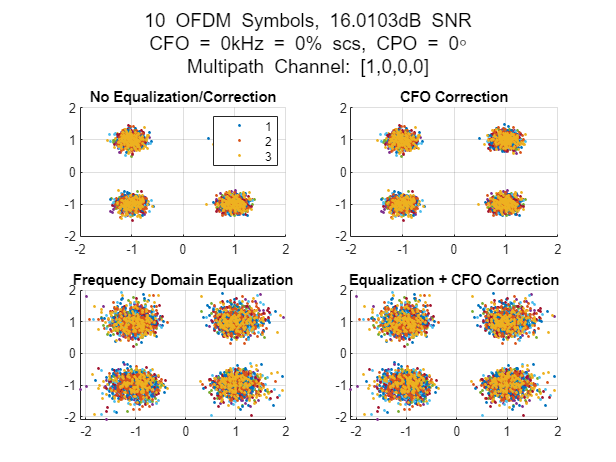

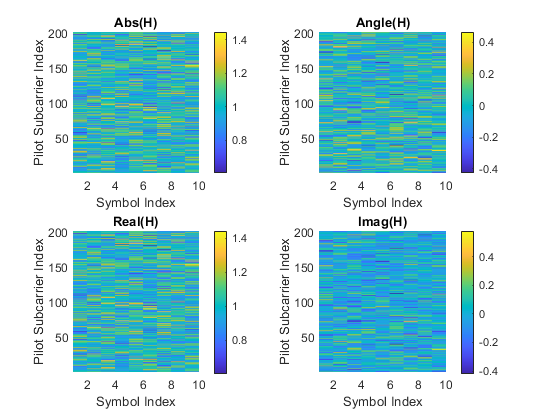

snr_test = ebno_test + 10*log10(log2(M));
ser = [];ser_eq = [];ser_cfo = [];ser_cfo_eq = [];
sigpower = pow2db(mean(abs(ofdm_signal).^2,'all'));
for i = 1:length(snr_test)
    [ofdm_awgn_signal,nvar] = awgn(ofdm_signal,snr_test(i),sigpower);
    if i == symbol_plot
        plot_v = 1;
    else
        plot_v = 0;
    end
    [dmod,dmod_eq,dmod_cfo,dmod_cfo_eq]=ofdm_receive(ofdm_awgn_signal,reference_pilot, ...
        nfft,BW,M,cp_len,ofdm_symbols,zp_index,pilot_index,rep,0,no_multi,snr_test(i),0,nvar,plot_v);
    tmp = symerr(mod_data,dmod)/numel(mod_data);
    if tmp == 0, tmp = 10^-99; end
    ser = [ser tmp];
    tmp = symerr(mod_data,dmod_eq)/numel(mod_data);
    if tmp == 0, tmp = 10^-99; end
    ser_eq = [ser_eq tmp];
    tmp = symerr(mod_data,dmod_cfo)/numel(mod_data);
    if tmp == 0, tmp = 10^-99; end
    ser_cfo = [ser_cfo tmp];
    tmp = symerr(mod_data,dmod_cfo_eq)/numel(mod_data);
    if tmp == 0, tmp = 10^-99; end
    ser_cfo_eq = [ser_cfo_eq tmp];
end

**AWGN + CFO Channel:**

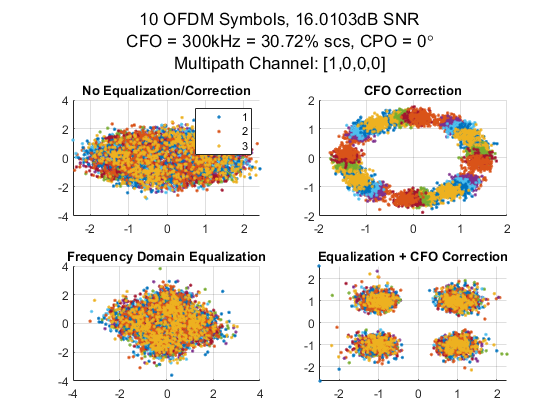

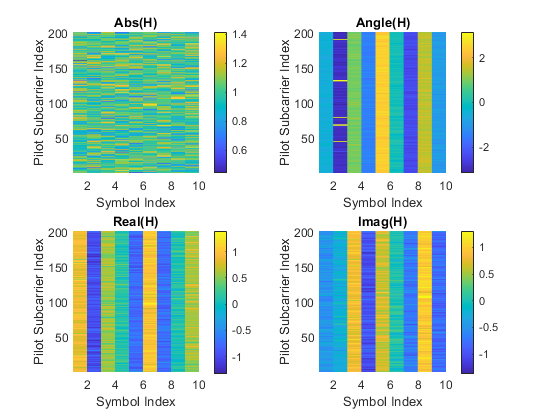

cfo = 300e3;
ser1 = [];ser_eq1 = [];ser_cfo1 = [];ser_cfo_eq1 = [];
sigpower = pow2db(mean(abs(ofdm_signal).^2,'all'));
for i = 1:length(snr_test)
    [ofdm_awgn_signal,nvar]=awgn(ofdm_signal,snr_test(i),sigpower);
    ofdm_awgn_signal = exp(1i*2*pi*cfo*t2)'.*ofdm_awgn_signal;
    if i == symbol_plot
        plot_v = 1;
    else
        plot_v = 0;
    end
    [dmod1,dmod_eq1,dmod_cfo1,dmod_cfo_eq1]=ofdm_receive(ofdm_awgn_signal,reference_pilot, ...
        nfft,BW,M,cp_len,ofdm_symbols,zp_index,pilot_index,rep,cfo,no_multi,snr_test(i),0,nvar,plot_v);
    tmp = symerr(mod_data,dmod1)/numel(mod_data);
    if tmp == 0, tmp = 10^-99; end
    ser1 = [ser1 tmp];
    tmp = symerr(mod_data,dmod_eq1)/numel(mod_data);
    if tmp == 0, tmp = 10^-99; end
    ser_eq1 = [ser_eq1 tmp];
    tmp = symerr(mod_data,dmod_cfo1)/numel(mod_data);
    if tmp == 0, tmp = 10^-99; end
    ser_cfo1 = [ser_cfo1 tmp];
    tmp = symerr(mod_data,dmod_cfo_eq1)/numel(mod_data);
    if tmp == 0, tmp = 10^-99; end
    ser_cfo_eq1 = [ser_cfo_eq1 tmp];
end

**AWGN + Multipath Channel:**

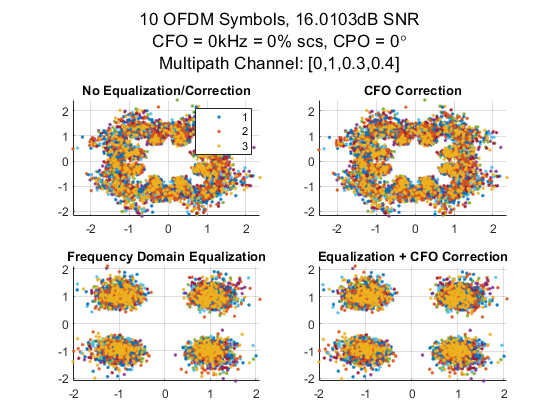

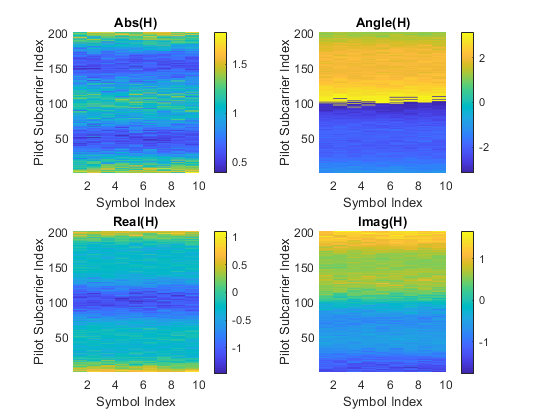

ser2 = [];ser_eq2 = [];ser_cfo2 = [];ser_cfo_eq2 = [];
sigpower = pow2db(mean(abs(ofdm_signal).^2,'all'));
multipath1 = [0 1 0.3 0.4];
for i = 1:length(snr_test)
    ofdm_awgn_signal = filter(multipath1,1,awgn(ofdm_signal,snr_test(i),sigpower));
    if i == symbol_plot
        plot_v = 1;
    else
        plot_v = 0;
    end
    [dmod2,dmod_eq2,dmod_cfo2,dmod_cfo_eq2]=ofdm_receive(ofdm_awgn_signal,reference_pilot, ...
        nfft,BW,M,cp_len,ofdm_symbols,zp_index,pilot_index,rep,0,multipath1,snr_test(i),0,nvar,plot_v);
    tmp = symerr(mod_data,dmod2)/numel(mod_data);
    if tmp == 0, tmp = 10^-99; end
    ser2 = [ser2 tmp];
    tmp = symerr(mod_data,dmod_eq2)/numel(mod_data);
    if tmp == 0, tmp = 10^-99; end
    ser_eq2 = [ser_eq2 tmp];
    tmp = symerr(mod_data,dmod_cfo2)/numel(mod_data);
    if tmp == 0, tmp = 10^-99; end
    ser_cfo2 = [ser_cfo2 tmp];
    tmp = symerr(mod_data,dmod_cfo_eq2)/numel(mod_data);
    if tmp == 0, tmp = 10^-99; end
    ser_cfo_eq2 = [ser_cfo_eq2 tmp];
end

**AWGN + CPO Channel**

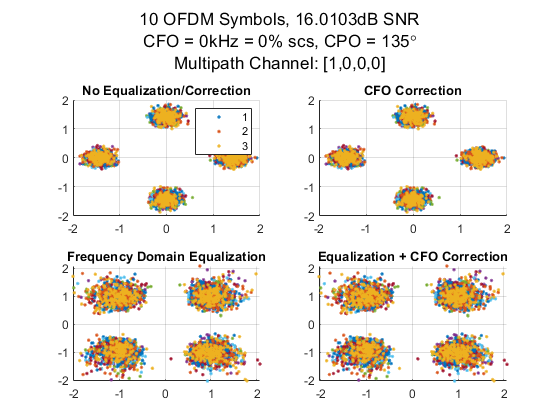

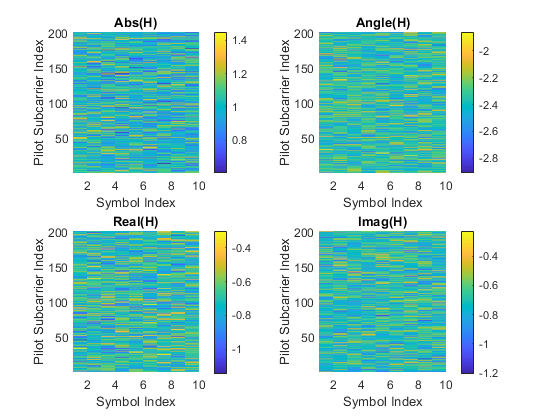

cpo = 3*pi/4;
ser1 = [];ser_eq1 = [];ser_cfo1 = [];ser_cfo_eq1 = [];
sigpower = pow2db(mean(abs(ofdm_signal).^2,'all'));
for i = 1:length(snr_test)
    [ofdm_awgn_signal,nvar]=awgn(ofdm_signal,snr_test(i),sigpower);
    ofdm_awgn_signal = exp(1i*cpo)'.*ofdm_awgn_signal;
    if i == symbol_plot
        plot_v = 1;
    else
        plot_v = 0;
    end
    [dmod1,dmod_eq1,dmod_cfo1,dmod_cfo_eq1]=ofdm_receive(ofdm_awgn_signal,reference_pilot, ...
        nfft,BW,M,cp_len,ofdm_symbols,zp_index,pilot_index,rep,0,no_multi,snr_test(i),cpo,nvar,plot_v);
    tmp = symerr(mod_data,dmod1)/numel(mod_data);
    if tmp == 0, tmp = 10^-99; end
    ser1 = [ser1 tmp];
    tmp = symerr(mod_data,dmod_eq1)/numel(mod_data);
    if tmp == 0, tmp = 10^-99; end
    ser_eq1 = [ser_eq1 tmp];
    tmp = symerr(mod_data,dmod_cfo1)/numel(mod_data);
    if tmp == 0, tmp = 10^-99; end
    ser_cfo1 = [ser_cfo1 tmp];
    tmp = symerr(mod_data,dmod_cfo_eq1)/numel(mod_data);
    if tmp == 0, tmp = 10^-99; end
    ser_cfo_eq1 = [ser_cfo_eq1 tmp];
end

**CFO + CPO + Multipath + Timing Offset + AWGN Channel**

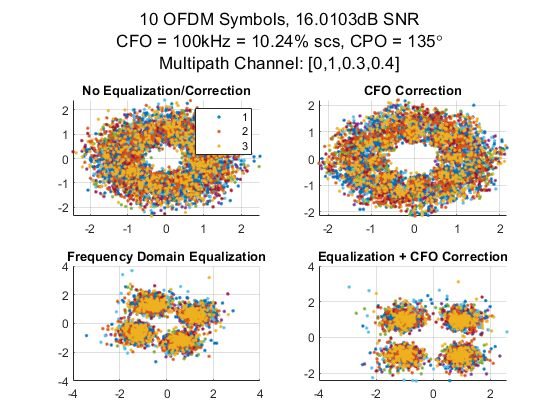

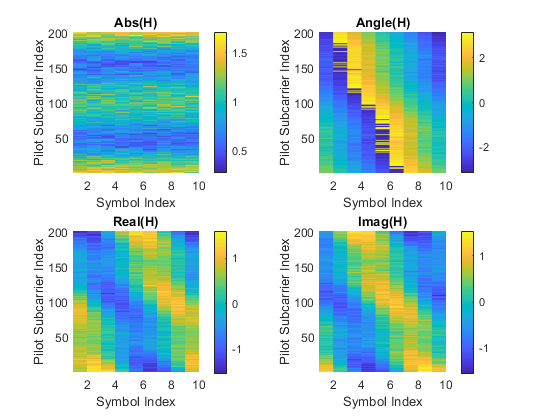

cfo = 100e3;
cpo = 3*pi/4;
ser1 = [];ser_eq1 = [];ser_cfo1 = [];ser_cfo_eq1 = [];
sigpower = pow2db(mean(abs(ofdm_signal).^2,'all'));
for i = 1:length(snr_test)
    ofdm_awgn_signal = exp(1i*cpo)*exp(1i*2*pi*cfo*t2)'.*ofdm_signal;
    ofdm_awgn_signal = filter(multipath1,1,ofdm_awgn_signal);
    [ofdm_awgn_signal,nvar]=awgn(ofdm_awgn_signal,snr_test(i),sigpower);
    if i == symbol_plot
        plot_v = 1;
    else
        plot_v = 0;
    end
    [dmod1,dmod_eq1,dmod_cfo1,dmod_cfo_eq1]=ofdm_receive(ofdm_awgn_signal,reference_pilot, ...
        nfft,BW,M,cp_len,ofdm_symbols,zp_index,pilot_index,rep,cfo,multipath1,snr_test(i),cpo,nvar,plot_v);
    tmp = symerr(mod_data,dmod1)/numel(mod_data);
    if tmp == 0, tmp = 10^-99; end
    ser1 = [ser1 tmp];
    tmp = symerr(mod_data,dmod_eq1)/numel(mod_data);
    if tmp == 0, tmp = 10^-99; end
    ser_eq1 = [ser_eq1 tmp];
    tmp = symerr(mod_data,dmod_cfo1)/numel(mod_data);
    if tmp == 0, tmp = 10^-99; end
    ser_cfo1 = [ser_cfo1 tmp];
    tmp = symerr(mod_data,dmod_cfo_eq1)/numel(mod_data);
    if tmp == 0, tmp = 10^-99; end
    ser_cfo_eq1 = [ser_cfo_eq1 tmp];
end

**Theoretical BER Values:**

ebno = -5:30;
[~,theo_ber] = berawgn(ebno,'qam',M);

**Test:**

% snr_convert = convertSNR(ebno_test,'ebno',BitsPerSymbol=log2(M));
% test_ser = [];test_ser1 = [];test_ser2 = [];
% for i=1:length(ebno_test)
%     data_test = randsrc(1024,1000,0:M-1);
%     qam_test = qammod(data_test,M,'UnitAveragePower',true);
%     sigpower = pow2db(mean(abs(qam_test).^2,'all'));
%     qam_test_awgn = awgn(qam_test,snr_test(i),sigpower);
%     qam_rec = qamdemod(qam_test_awgn,M,'UnitAveragePower',true);
%     test_ser = [test_ser symerr(data_test,qam_rec)/numel(data_test)];
%     [tmp_ser1,tmp_ser2] = symerr(data_test,qam_rec);
%     test_ser1 = [test_ser1 tmp_ser1];
%     test_ser2 = [test_ser2 tmp_ser2];
% end


**Plot:**

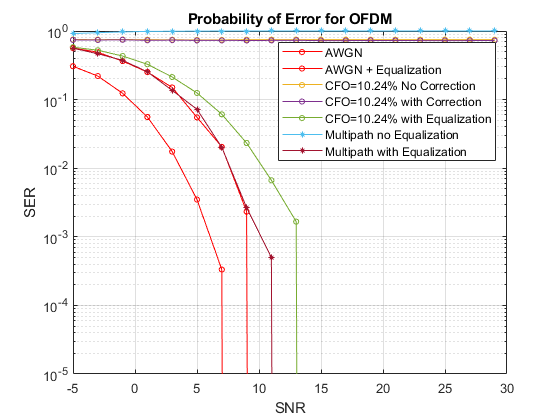

markersize = 4;
figure()%,semilogy(ebno,theo_ber),hold on
%semilogy(ebno_test,test_ser,'*'),
semilogy(ebno_test,ser,'r-o','MarkerSize',markersize),hold on
semilogy(ebno_test,ser_eq,'r-o','MarkerSize',markersize),hold on
semilogy(ebno_test,ser1,'-o','MarkerSize',markersize)
semilogy(ebno_test,ser_cfo1,'-o','MarkerSize',markersize)
semilogy(ebno_test,ser_cfo_eq1,'-o','MarkerSize',markersize)
semilogy(ebno_test,ser2,'-*','MarkerSize',markersize)
semilogy(ebno_test,ser_eq2,'-*','MarkerSize',markersize)
ylim([10^-5 1]),grid on,xlim([-5 30])
%legend({['Theoretical ',num2str(M),'-QAM'],'OFDM awgn'})
legend('AWGN','AWGN + Equalization',['CFO=',num2str(cfo/scs*100),'% No Correction'],['CFO=',num2str(cfo/scs*100),'% with Correction'], ...
    ['CFO=',num2str(cfo/scs*100),'% with Equalization'],'Multipath no Equalization', ...
    'Multipath with Equalization')
title('Probability of Error for OFDM'),xlabel('SNR'),ylabel('SER')